# Comprobación para topología usada en NaiveDijkstra

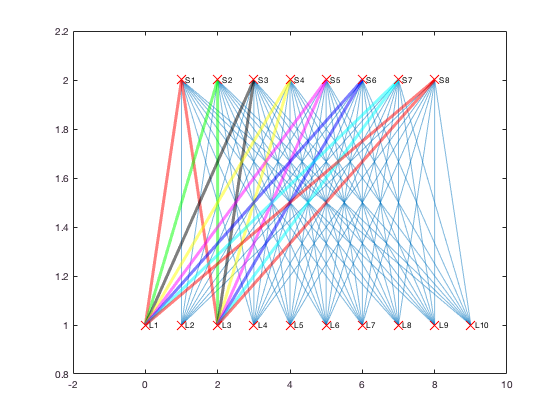

N=10;%Number of disjoint links to compute
topology='SpineLeaf';
k=8;
source='L1';
dest='L3';

G=graphTopology(false,false,topology,k,10);

paths=edgeDisjointPair(G,source,dest,N,false);

%See the plot

p=plotGraphtopology(G);
plotPaths(p, paths);

# Comparación DisjointPair con NaiveDijkstra

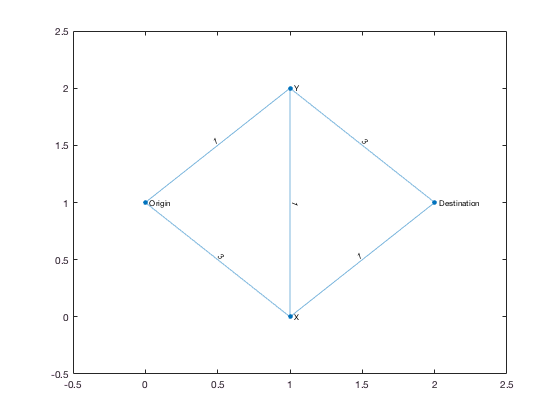

nnodes=4;
N=3;
% Nodes Table
endnodes = cell(nnodes, 1);
Xpoint(nnodes,1)=1;
Ypoint(nnodes,1)=1;
endnodes{1}='Origin';
Xpoint(1,1)=0;
Ypoint(1,1)=1;
endnodes{2}='Y';
Xpoint(2,1)=1;
Ypoint(2,1)=2;
endnodes{3}='X';
Xpoint(3,1)=1;
Ypoint(3,1)=0;
endnodes{4}='Destination';
Xpoint(4,1)=2;
Ypoint(4,1)=1;
nodestable = table(endnodes,Xpoint,Ypoint,'VariableNames',{'Name';'Xpoint';'Ypoint'});

NetCostMatrix=[0 1 3 0; 1 0 1 3; 3 1 0 1; 0 3 1 0];

%edgetable = table(edges,costs,'VariableNames',{'EndNodes';'Weight'});
edgetable = edgeTableCostMatrix(NetCostMatrix);
G=graph(edgetable,nodestable);

p = plot(G,'XData',G.Nodes.Xpoint','YData',G.Nodes.Ypoint','NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);

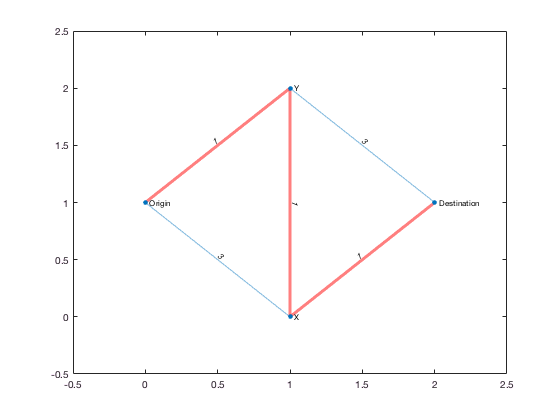

paths=edgeDisjointNaiveDijkstra(NetCostMatrix,1,4,N,true);
%See the plot

p = plot(G,'XData',G.Nodes.Xpoint','YData',G.Nodes.Ypoint','NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
plotPaths(p, paths);

## El NaiveDijkstra solo encuentra una ruta disjunta

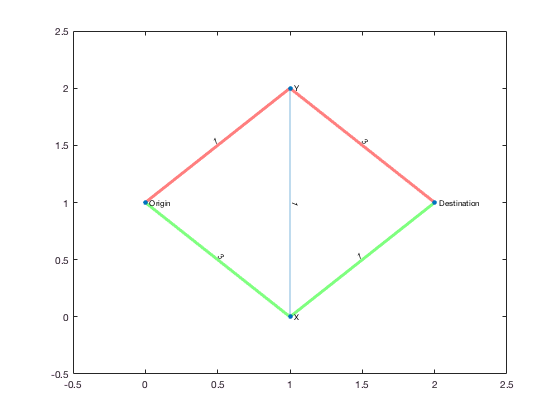

paths=edgeDisjointPair(NetCostMatrix,1,4,N,true);
%See the plot

p = plot(G,'XData',G.Nodes.Xpoint','YData',G.Nodes.Ypoint','NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
plotPaths(p, paths);

## El DisjointPair encuentra dos rutas disjuntas

nnodes=5;
N=4;
% Nodes Table
endnodes = cell(nnodes, 1);
Xpoint(nnodes,1)=1;
Ypoint(nnodes,1)=1;
endnodes{1}='Origin';
%Xpoint(1,1)=0;
%Ypoint(1,1)=1;
endnodes{2}='2';
%Xpoint(2,1)=1;
%Ypoint(2,1)=2;
endnodes{3}='3';
endnodes{4}='4';
%Xpoint(3,1)=1;
%Ypoint(3,1)=0;
endnodes{5}='Destination';
%Xpoint(4,1)=2;
%Ypoint(4,1)=1;
nodestable = table(endnodes,'VariableNames',{'Name'});

NetCostMatrix=[0 1 4 4 0; 1 0 1 0 4; 4 1 0 1 4; 4 0 1 0 1 ; 0 4 4 1 0];

edgetable = edgeTableCostMatrix(NetCostMatrix);
G=graph(edgetable,nodestable);
p = plot(G,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
%NaiveDijkstra
paths=edgeDisjointNaiveDijkstra(NetCostMatrix,1,5,N,true);
plotPaths(p, paths);

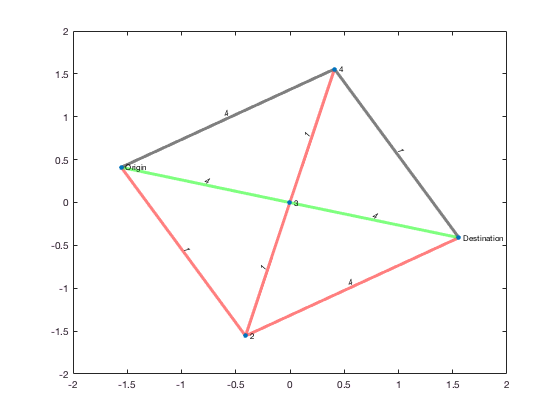


%DisjointPair
paths=edgeDisjointPair(NetCostMatrix,1,5,N,true);
p = plot(G,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
plotPaths(p, paths);